clear; close all;

Treatment = "ChemoBiM2";
Protocol  = "ThreeFPHoldSRT";
Subject   = "Naveed";

Drives = string(char('A':'Z')');
for i = 1:26
    folder_i = Drives(i)+":\OneDrive";
    if isfolder(folder_i)
        WorkFolder = fullfile(folder_i, "YuLab\GPS_Project\Scripts");
    end
end

DataFolder = fullfile(WorkFolder, "Data", Treatment, Protocol, Subject);

FigFolder  = fullfile(WorkFolder, "Figures", Treatment, Protocol, Subject);
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

DataFile = dir(fullfile(DataFolder, "*Traj*.mat"));
if isempty(DataFile)
    error('No traj data files here');
elseif length(DataFile)>1
    error('More than one traj data file')
end

load(fullfile(DataFolder, DataFile.name));


info = obj.TrialInfo;

id_pre = info.Outcome=="Premature" & info.HD>.5 & info.FP>.5 & info.Stage==1;
id_pre_l_ctrl = id_pre & info.PortCorrect==1 & info.Label=="Control";
id_pre_r_ctrl = id_pre & info.PortCorrect==2 & info.Label=="Control";
id_pre_l_chemo = id_pre & info.PortCorrect==1 & info.Label=="Chemo";
id_pre_r_chemo = id_pre & info.PortCorrect==2 & info.Label=="Chemo";

id_cor = info.Outcome=="Correct" & info.HD>.5 & info.FP>.5 & info.Stage==1;
id_cor_l_ctrl = id_cor & info.PortCorrect==1 & info.Label=="Control";
id_cor_r_ctrl = id_cor & info.PortCorrect==2 & info.Label=="Control";
id_cor_l_chemo = id_cor & info.PortCorrect==1 & info.Label=="Chemo";
id_cor_r_chemo = id_cor & info.PortCorrect==2 & info.Label=="Chemo";


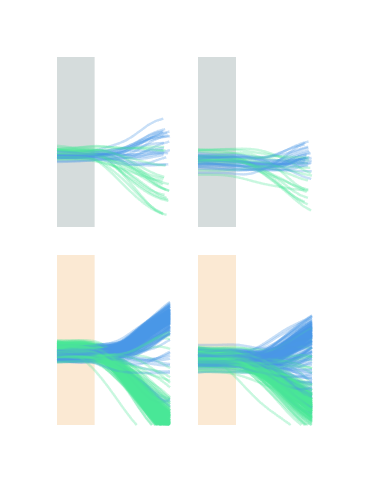

plt = GPSPlot();
feature = "PosXHead";
xlimit = [-100 200];
ylimit = [-200 300];

fig = figure(11); clf(11);
set(fig, 'visible', 'on', 'Units', 'centimeters', 'Position', [15 10 6.5 8.5], 'Color', 'w');

ax = axes('XLim', xlimit, 'YLim', ylimit, 'Units', 'centimeters', 'Position', [1 4.5 2 3], 'XColor', 'none', 'YColor', 'none');
obj.plot_trace(ax, obj.TimeFromOut(id_pre_l_ctrl), obj.(feature)(id_pre_l_ctrl), 'color', GPSColor.PortL);
obj.plot_trace(ax, obj.TimeFromOut(id_pre_r_ctrl), obj.(feature)(id_pre_r_ctrl), 'color', GPSColor.PortR);
plt.add_shade(ax, [xlimit(1) 0], 'color', GPSColor.Control, 'alpha', .2);

ax = axes('XLim', xlimit, 'YLim', ylimit, 'Units', 'centimeters', 'Position', [3.5 4.5 2 3], 'XColor', 'none', 'YColor', 'none');
obj.plot_trace(ax, obj.TimeFromOut(id_pre_l_chemo), obj.(feature)(id_pre_l_chemo), 'color', GPSColor.PortL);
obj.plot_trace(ax, obj.TimeFromOut(id_pre_r_chemo), obj.(feature)(id_pre_r_chemo), 'color', GPSColor.PortR);
plt.add_shade(ax, [xlimit(1) 0], 'color', GPSColor.Control, 'alpha', .2);

ax = axes('XLim', xlimit, 'YLim', ylimit, 'Units', 'centimeters', 'Position', [1 1 2 3], 'XColor', 'none', 'YColor', 'none');
obj.plot_trace(ax, obj.TimeFromOut(id_cor_l_ctrl), obj.(feature)(id_cor_l_ctrl), 'color', GPSColor.PortL);
obj.plot_trace(ax, obj.TimeFromOut(id_cor_r_ctrl), obj.(feature)(id_cor_r_ctrl), 'color', GPSColor.PortR);
plt.add_shade(ax, [xlimit(1) 0], 'color', GPSColor.Treat, 'alpha', .2);

ax = axes('XLim', xlimit, 'YLim', ylimit, 'Units', 'centimeters', 'Position', [3.5 1 2 3], 'XColor', 'none', 'YColor', 'none');
obj.plot_trace(ax, obj.TimeFromOut(id_cor_l_chemo), obj.(feature)(id_cor_l_chemo), 'color', GPSColor.PortL);
obj.plot_trace(ax, obj.TimeFromOut(id_cor_r_chemo), obj.(feature)(id_cor_r_chemo), 'color', GPSColor.PortR);
plt.add_shade(ax, [xlimit(1) 0], 'color', GPSColor.Treat, 'alpha', .2);